clear 
clc

addpath '.\INM'
addpath '.\SD'
addpath '.\FR'
addpath '.\functions'

load('forcing_terms.mat')
load('test_functions2.mat')
load('myFunctions.mat')

%Armijo
c1 = 1e-4;
rho = 0.5;
btmax = 50;
alpha0 = 5;

%Step for finite differences
h = 1e-8;

%Problem definition
n = 1000;
x0 = x16(n);
f = f16;
gradf = gf16;
Hessf = 0;

kmax = 50000;
tolgrad = 1.0E-6;
toldiffgrad = 1e-12;

% max number of iterations for the pcg
pcg_maxit = 200;

run_newton = true;
run_steepest = true;
run_fletcher = true;

## Run Steepest Descent

if run_steepest
    tic
    disp('***Steepest Descent: start***')
    [xk_sd, fk_sd, gradfk_norm_sd, k_sd, xseq_sd, btseq_sd, fseq_sd, gfseq_sd] = ... 
        steepest_desc_bt(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax);
    
    disp('***Steepest Descent: finished')
    toc
    disp('***SD: results')
    disp('*******')
    disp(['xk: ', mat2str(xk_sd)])
    disp(['f(xk): ', mat2str(fk_sd)])
    disp(['gradf(xk): ', mat2str(gradfk_norm_sd)])
    disp(['N of iterations: ', num2str(k_sd), '/', num2str(kmax), ';'])
    disp(['fseq: ', mat2str(fseq_sd)])
    disp(['gfseq: ', mat2str(gfseq_sd)])
    
    disp('****')
else
    disp("SD Method not runned")
end

***Steepest Descent: start***


Iteration 1 gf_norm: 10874.450216
Iteration 2 gf_norm: 9993.078832
Iteration 3 gf_norm: 9548.659925
Iteration 4 gf_norm: 9294.343403
Iteration 5 gf_norm: 9139.938989
Iteration 6 gf_norm: 9033.811230
Iteration 7 gf_norm: 620.240588
Iteration 8 gf_norm: 439.446281
Iteration 9 gf_norm: 333.946491
Iteration 10 gf_norm: 263.712200
Iteration 11 gf_norm: 494.626330
Iteration 12 gf_norm: 358.147491
Iteration 13 gf_norm: 140.787901
Iteration 14 gf_norm: 111.191369
Iteration 15 gf_norm: 209.330445
Iteration 16 gf_norm: 155.018549
Iteration 17 gf_norm: 116.937812
Iteration 18 gf_norm: 90.364157
Iteration 19 gf_norm: 72.041976
Iteration 20 gf_norm: 59.604369
Iteration 21 gf_norm: 105.320852
Iteration 22 gf_norm: 80.492885
Iteration 23 gf_norm: 63.420214
Iteration 24 gf_norm: 51.931538
Iteration 25 gf_norm: 96.933521
Iteration 26 gf_norm: 73.681767
Iteration 27 gf_norm: 57.673161
Iteration 28 gf_norm: 46.909605
Iteration 29 gf_norm: 89.858752
Iteration 30 gf_norm: 68.092517
Iteration 31 gf_norm: 53

***Steepest Descent: finished


Elapsed time is 113.162106 seconds.


***SD: results


*******


xk: [-1.10714628326173;-0.785398124291639;-0.588002603327072;-0.46364760900007;-0.380506377112363;-0.321750554396642;-0.278299659005111;-0.244978663126864;-0.218668945873942;-0.197395559849881;-0.179853499792478;-0.165148677414627;-0.152649328395265;-0.141897054604164;-0.132551532296674;-0.124354994546762;-0.117108744566864;-0.110657221173896;-0.104876938730234;-0.0996686524911622;-0.0949517063427563;-0.0906598872007452;-0.0867383386759852;-0.0831412318884413;-0.0798299857122374;-0.076771891269778;-0.0739390376579403;-0.0713074647852904;-0.0688564893010447;-0.0665681637758239;-0.0644268394255536;-0.0624188099959574;-0.0605320197821072;-0.0587558227157229;-0.0570807824062648;-0.055498505245717;-0.0540015003759684;-0.0525830616109418;-0.0512371674034189;-0.0499583957219429;-0.0487418513099317;-0.0475831032769836;-0.046478131351003;-0.0454232794215771;-0.0444152152469109;-0.0434508953915309;-0.0425275346197842;-0.0416425790985885;-0.0407936828678654;-0.0399786871232901;-0.0391956019270547

f(xk): -427.404476374842


gradf(xk): 6.20105121582726e-06


N of iterations: 50000/50000;


fseq: [87644.4802574171 68903.6566211927 62370.4625287827 57123.6246994567 55934.1456088461 53310.4291623389 232.832903549351 98.6520278921284 20.6622641441706 -35.2281748064807 -38.0097179824682 -106.49155392959 -320.514374972409 -330.78716405 -331.39363728835 -342.677515880346 -349.998584680683 -355.13585171888 -359.011240720544 -362.121218798549 -363.930185913665 -367.485510943457 -370.140376834901 -372.277603835086 -372.990379020505 -375.788597993929 -377.854992254479 -379.511141365185 -379.801425396822 -382.112931090702 -383.804682303944 -385.153160397605 -385.246149435429 -388.593461476344 -399.224109733266 -404.921256287794 -408.119409141601 -410.011833481656 -411.206043868336 -412.018152135499 -412.615070227931 -413.086058792962 -413.177850611664 -413.79476732041 -414.237788856945 -414.582428530262 -414.869020662129 -415.04937844144 -415.400522983178 -415.670378454364 -415.893533232232 -416.004716700483 -416.293736629829 -416.513889442585 -416.69515984062 -416.768705432128 -417

gfseq: [10874.4502161023 9993.07883164587 9548.65992509086 9294.34340266849 9139.93898867994 9033.81123038679 620.24058759099 439.446281327396 333.94649077254 263.712199996234 494.626329935199 358.147490529185 140.787900790425 111.191368844019 209.330444916865 155.018549030128 116.937811525955 90.3641571074003 72.0419762196171 59.6043691332875 105.32085190587 80.492885496852 63.4202140499904 51.9315377710791 96.9335214518823 73.6817667821701 57.6731612819276 46.9096053085066 89.8587520900589 68.0925168002732 53.0805338219581 42.9772291434568 83.5510016853227 240.310560390877 173.429066758725 126.055352478811 92.2448412198909 68.091102698973 50.9073858231194 38.7944366489586 30.3786060525745 24.6394374909495 46.75969266881 35.3374205924775 27.3818609547611 21.9541287260319 18.3382779988109 32.5851500839803 25.0847003115872 19.9595239616061 16.5489876239004 30.2290851705351 23.1768310000355 18.3520120248884 15.1425558498106 28.1415056149259 21.5249200682811 16.9957487167814 13.9849530000

****


## Run Fletcher Reeves

if run_steepest
    tic
    disp('***Fletcher Reeves: start***')
    [xk_fr, fk_fr, gradfk_norm_fr, k_fr, xseq_fr, btseq_fr, fseq_fr, gfseq_fr] = ... 
        fletcher_reeves(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax);
    
    disp('***Fletcher Reeves: finished')
    toc
    disp('***FR: results')
    disp('*******')
    disp(['xk: ', mat2str(xk_fr)])
    disp(['f(xk): ', mat2str(fk_fr)])
    disp(['gradf(xk): ', mat2str(gradfk_norm_fr)])
    disp(['N of iterations: ', num2str(k_fr), '/', num2str(kmax), ';'])
    disp(['fseq: ', mat2str(fseq_fr)])
    disp(['gfseq: ', mat2str(gfseq_fr)])
    
    disp('****')
else
    disp("FR Method not runned")
end

***Fletcher Reeves: start***


Iteration 1 gf_norm: 10874.450216
Iteration 2 gf_norm: 5837.707488
Iteration 3 gf_norm: 5436.522296
Iteration 4 gf_norm: 4436.883689
Iteration 5 gf_norm: 2743.462850
Iteration 6 gf_norm: 1746.571130
Iteration 7 gf_norm: 1102.563423
Iteration 8 gf_norm: 729.619885
Iteration 9 gf_norm: 483.218148
Iteration 10 gf_norm: 338.409861
Iteration 11 gf_norm: 404.970758
Iteration 12 gf_norm: 407.155402
Iteration 13 gf_norm: 285.900901
Iteration 14 gf_norm: 216.687263
Iteration 15 gf_norm: 275.344819
Iteration 16 gf_norm: 274.718486
Iteration 17 gf_norm: 257.501114
Iteration 18 gf_norm: 245.871819
Iteration 19 gf_norm: 256.022779
Iteration 20 gf_norm: 251.888488
Iteration 21 gf_norm: 200.807032
Iteration 22 gf_norm: 225.566423
Iteration 23 gf_norm: 220.003616
Iteration 24 gf_norm: 170.855705
Iteration 25 gf_norm: 162.327034
Iteration 26 gf_norm: 171.306385
Iteration 27 gf_norm: 165.553034
Iteration 28 gf_norm: 149.371647
Iteration 29 gf_norm: 145.447779
Iteration 30 gf_norm: 114.446084
Iteration 3

***Fletcher Reeves: finished


Elapsed time is 136.668881 seconds.


***FR: results


*******


xk: [-1.10714823057848;-0.785396921091787;-0.588001577343584;-0.463647602940413;-0.380505734402151;-0.321750329591609;-0.278299624474793;-0.244977846799755;-0.218669074910054;-0.197395440547015;-0.179853506176912;-0.165148629624314;-0.152649382601241;-0.141897262256479;-0.132551334401941;-0.12435502187539;-0.117108751951656;-0.11065720223005;-0.104876927491363;-0.099668531379966;-0.0949516674823454;-0.090659896574088;-0.086738375638605;-0.0831411912328312;-0.0798300763629606;-0.0767717807221911;-0.0739391441992477;-0.0713074641682157;-0.0688564914156613;-0.0665681088167748;-0.0644269137066666;-0.0624188186790473;-0.0605320028054434;-0.0587558402144121;-0.0570807246442562;-0.0554985288521696;-0.0540014946442111;-0.0525831180111021;-0.0512371231439789;-0.0499583328536307;-0.0487419300773375;-0.0475831027883152;-0.0464781180606547;-0.045423270448796;-0.044415216979434;-0.0434509426532897;-0.0425274838889815;-0.041642563629768;-0.040793757940991;-0.0399786683591439;-0.0391955693200611;-0.0

f(xk): -427.404476374835


gradf(xk): 6.29657072157606e-05


N of iterations: 50000/50000;


fseq: [87644.4802574171 30474.3013798367 19548.6871682793 14303.2985161917 5423.76472832872 2083.55172630423 672.518034272513 190.862705533582 -58.0164119530451 -165.796774378018 -171.072178465245 -180.696145650083 -269.298361019034 -309.152231719784 -311.396661541923 -312.587438761946 -337.459506449883 -344.353876540377 -347.12707783855 -348.142302606603 -357.348214933761 -363.875951823223 -365.020003799677 -371.529911322884 -377.402149724194 -380.365604639667 -380.90549254456 -386.546782673131 -391.54884367996 -396.710752672066 -399.475871119824 -400.014497042769 -400.152792884414 -401.7456605742 -401.968731876682 -403.913771712845 -405.947010828762 -406.64995731613 -407.894365241327 -409.737303728975 -410.657946083624 -411.587294572486 -413.310072627991 -414.620785265389 -414.69923869416 -414.716945575623 -415.926326196591 -416.759043366622 -416.89891537269 -417.041349194232 -417.821178150655 -418.012894532716 -419.303881213903 -420.079096244858 -420.384118281798 -420.730179421278 -

gfseq: [10874.4502161023 5837.7074879561 5436.52229629948 4436.883688756 2743.46285012626 1746.57113029815 1102.5634225329 729.619885109644 483.218147829195 338.409861420399 404.97075848878 407.155401767198 285.900901199968 216.687263499515 275.344818600998 274.718485639376 257.501113581023 245.871819181149 256.022778908214 251.888488496396 200.807032420245 225.566422825342 220.003616167333 170.855704893323 162.327034136237 171.306384705159 165.553033639656 149.371646623156 145.447778772693 114.446083846222 103.206695585811 140.788640027175 142.9494199683 124.384209718601 139.720279395623 142.676092252452 115.504605109504 109.970438947923 111.658517738046 91.4754638835979 79.1076971672357 82.1290259409515 72.0846513879494 55.1601144097666 76.1293414745773 82.0716221014257 68.4788633065202 67.0013635204629 90.8064329630909 89.2865690366295 70.7060085952324 71.5881448045775 63.7278329739629 48.3137918970783 43.5922354194949 43.2676321183838 36.4948199732937 32.5620917591967 46.1845447790

****


## Run the Newton

if run_newton
%     fterms = @(gradf, x, k) 0.5;
%    fterms = @(gradfk, k) min(0.5, sqrt(norm(gradfk)));
     fterms = @(gradfk, k) min(0.5, norm(gradfk));
    
    % options for finite differences
    FDgrad = '-c';
    FDHess = 'Jc';
    
    disp('***NEWTON F.D. options***')
    disp(['FDgrad: ', FDgrad])
    disp(['FDHess: ', FDHess])
    
    disp('***Newton: start***')
    tic
    [xk, fk, gradfk_norm, k, xseq, btseq, fseq, gfseq] = ...
        innewton_general(x0, f, gradf, Hessf, kmax, ...
        tolgrad, toldiffgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit);
    
    disp('***IN. newton: finished')
    toc
    disp('***newton: results')
    disp('*******')
    disp(['xk: ', mat2str(xk)])
    disp(['f(xk): ', mat2str(fk)])
    disp(['gradf(xk): ', mat2str(gradfk_norm)])
    disp(['N of iterations: ', num2str(k), '/', num2str(kmax), ';'])
    disp(['fseq: ',mat2str(fseq)])
    disp(['gfseq: ',mat2str(gfseq)])

    disp('****')
else
    disp("Newton Method not runned")
end

***NEWTON F.D. options***


FDgrad: -c


FDHess: Jc


***Newton: start***


Hessian non-PD
Cond(H): 22260.511837
pcg converged at iteration 1 to a solution with relative residual 0.26.
Iteration 0 gf_norm: 11149.647651
Hessian non-PD
Cond(H): 40826.110597
pcg converged at iteration 1 to a solution with relative residual 0.16.
Iteration 1 gf_norm: 5099.347817
Hessian non-PD
Cond(H): 157637.564679
pcg converged at iteration 1 to a solution with relative residual 0.19.
Iteration 2 gf_norm: 1216.270053
Hessian non-PD
Cond(H): 137359.643672
pcg converged at iteration 3 to a solution with relative residual 0.33.
Iteration 3 gf_norm: 406.134434
Hessian non-PD
Cond(H): 10608.331324
pcg converged at iteration 4 to a solution with relative residual 0.38.
Iteration 4 gf_norm: 152.318247
Hessian non-PD
Cond(H): 4592.574755
pcg converged at iteration 6 to a solution with relative residual 0.48.
Iteration 5 gf_norm: 73.000347
Hessian non-PD
Cond(H): 15410.828762
pcg converged at iteration 4 to a solution with relative residual 0.46.
Iteration 6 gf_norm: 33.366363
Hessian no

***IN. newton: finished


Elapsed time is 8.380676 seconds.


***newton: results


*******


xk: [-7.39033402497351;-0.785398163397774;-0.588002603547344;-0.463647609000925;-0.380506377112714;-0.321750554396637;-0.278299659005025;-0.244978663127026;-0.218668945872859;-0.197395559850034;-0.179853499792924;-0.165148677414167;-0.152649328394853;-0.141897054603715;-0.132551532296898;-0.124354994545923;-0.117108744566881;-0.110657221173328;-0.104876938730702;-0.0996686524905223;-0.0949517063426203;-0.090659887200629;-0.0867383386763249;-0.0831412318884925;-0.0798299857121078;-0.076771891269705;-0.073939037657844;-0.0713074647855417;-0.0688564893008545;-0.0665681637758608;-0.0644268394256104;-0.0624188099957161;-0.0605320197821515;-0.0587558227157246;-0.0570807824062672;-0.0554985052458168;-0.0540015003758965;-0.0525830616109813;-0.051237167403573;-0.0499583957219528;-0.0487418513099279;-0.047583103276927;-0.046478131350771;-0.0454232794213652;-0.0444152152468545;-0.0434508953915505;-0.042527534619793;-0.0416425790985813;-0.0407936828678891;-0.0399786871232988;-0.0391956019269685;-0

f(xk): -427.404476374849


gradf(xk): 9.11907431498934e-11


N of iterations: 18/50000;


fseq: [92694.2583472476 18215.1137519833 3182.77728638654 215.707933620771 -297.705065312242 -393.207297495266 -405.787493583708 -420.903098562335 -423.761982850858 -426.63590010154 -427.358077567588 -427.390047569757 -427.401561584351 -427.402712810923 -427.404436762221 -427.404476168099 -427.404476374849 -427.404476374849]


gfseq: [11149.6476511351 5099.34781736994 1216.270052805 406.134434198996 152.318246557247 73.0003465559947 33.366363104004 16.1872765644428 8.5680457410503 5.36014403752805 2.4301692411832 1.19431987742536 0.540060616723819 0.253447570435185 0.0562549184907641 0.00313157509657778 9.55688757709894e-06 9.11907431498934e-11]


****


disp('===========================================================================================================================================================================')

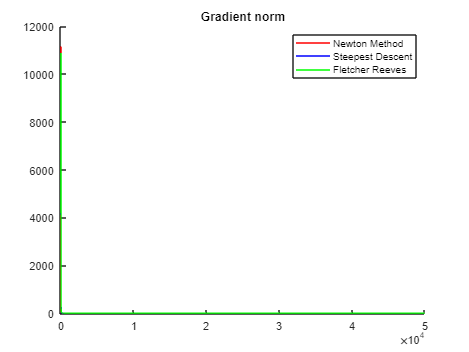


figure(1);
hold on;
title("Gradient norm")
plot(linspace(0,k,k), gfseq, "r")
plot(linspace(0,k_sd,k_sd), gfseq_sd, "b")
plot(linspace(0,k_fr,k_fr), gfseq_fr, "g")
legend(["Newton Method", "Steepest Descent", "Fletcher Reeves"])
hold off

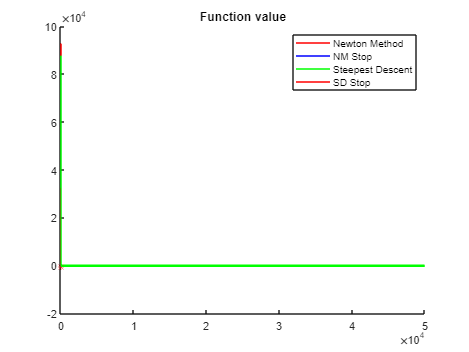

figure(3);
hold on;
title("Function value")
plot(linspace(0,k,k), fseq, "r")
plot(k, fseq(k), "*r")
plot(linspace(0,k_sd,k_sd), fseq_sd, "b")
plot(k_sd, fseq_sd(k_sd), "*b")

plot(linspace(0,k_fr, k_fr), fseq_fr, "g")
plot(k_fr, fseq_fr(k_fr), "*g")
legend("Newton Method","NM Stop", "Steepest Descent", "SD Stop")
hold off;